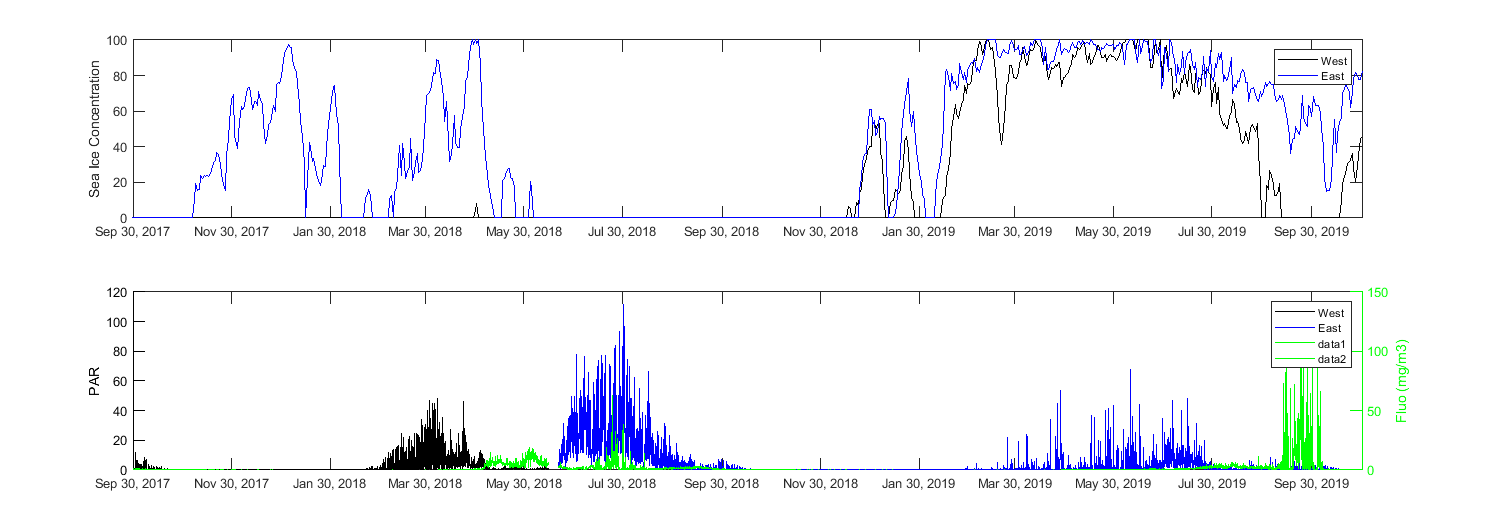

clearvars; close('all')

load sea_ice_concentration.mat

% prize west
PWN=81.2;
PWS=81;
PWE=19;
PWW=18;
lnid=LON>=PWW & LON<=PWE;
ltid=LAT>=PWS & LAT<=PWN;
idx=lnid<id;

% prize east
PEN=81.4;
PES=81.2;
PEE=32;
PEW=31;
lnid=LON>=PEW & LON<=PEE;
ltid=LAT>=PES & LAT<=PEN;
idk=lnid<id;

for cc=1:numel(ice_conc(1,1,:))
    tmpconc=ice_conc(:,:,cc);
    ice_arrayW(cc)=nanmean(tmpconc(idx));
    ice_arrayE(cc)=nanmean(tmpconc(idk));
end

figure('units','centimeters','outerposition',[2 2 40 15]);

tiledlayout(2,1)
nexttile
h1=plot(date_time,ice_arrayW,'k-');
hold on
h2=plot(date_time,ice_arrayE,'b-');
ylabel('Sea Ice Concentration');
legend([h1 h2],'West',['East']);
xlim(datetime(["30.09.2017 00:00:00" "31.10.2019 00:00:00"], 'InputFormat', 'dd.MM.yyyy HH:mm:ss'))
xticks(datetime("30.09.2017",'InputFormat', 'dd.MM.yyyy') : calmonths(2) : datetime('31.10.2019','InputFormat', 'dd.MM.yyyy'))
load ('C:\Users\sa01ld\OneDrive - SAMS\Projects\PRIZE\BODC_submission\EAST_18.mat')
load ('C:\Users\sa01ld\OneDrive - SAMS\Projects\PRIZE\BODC_submission\WEST_17.mat')
x=prize_west_17(1).time;
y=prize_west_17(1).par;
nexttile
yyaxis left
h1=plot(x,y,'k-');
hold on
x=prize_east_18(1).time;
y=prize_east_18(1).par;
y2=prize_east_18(1).fluo;
h2=plot(x,y,'b-');
ylabel('PAR')
legend([h1 h2],'West','East');
yyaxis right
plot(x,y2,'g-');
x=prize_west_17(1).time;
y=prize_west_17(1).fluo;
hold on
plot(x,y,'g-');
ylabel('Fluo (mg/m3)')
ylim([0 150])
ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'g';
xlim(datetime(["30.09.2017" "31.10.2019"], 'InputFormat', 'dd.MM.yyyy'))
xticks(datetime("30.09.2017",'InputFormat', 'dd.MM.yyyy') : calmonths(2) : datetime('31.10.2019','InputFormat', 'dd.MM.yyyy'))
print(gcf,'-dpng','Ice_cover_par');